my_data = dlmread('D:\GitHub Repositories\GaN-Studies\Protection Circuits\VgsBottom.txt','',1,0);
t = my_data(:,1);
Vgs = my_data(:,2);
dIdtSim = my_data(:,3);


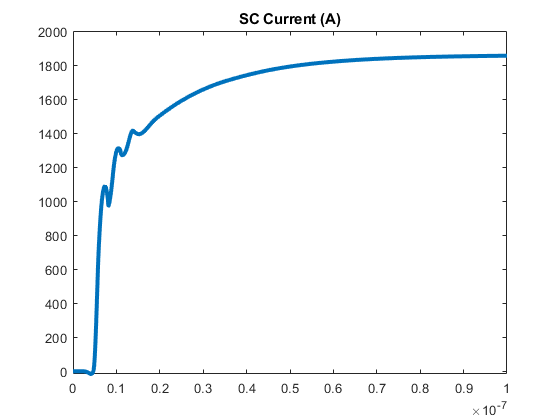


Tj = 25; % + 100/150e-9*t;
K1 = 90.8-0.387*(Tj - 25);
K2 = 1/26;
K3 = 1.1;
K4 = 1.1;
K5 = 1;
Vth = 1.7;

sizet = size(t,1);
for i=2:sizet
    dVgsdt(i) = (Vgs(i) - Vgs(i-1))/(t(i) -t(i-1));
end
dVgsdt = movmean(dVgsdt,10);
for i=2:sizet
    e(i) = exp((Vgs(i)-Vth)/K2);
    p(i) = Vgs(i)+K5+K3/K4;
    dIdVgs(i) = K1./(K4*Vgs(i))*(e(i)/(K2*(1+e(i))) - log(1+e(i))/p(i));
end
dIdt = dIdVgs.*dVgsdt;
dIdt = lowpass(dIdt,2e-10,200e6);
Rsense = 0e-3;
I = customintegral(t,dIdt);
figure
plot(t,I,'LineWidth',3);
title('SC Current (A)')

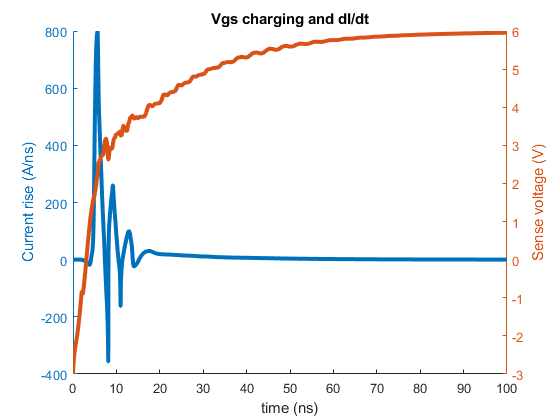


% VsenseBuilt = 10e-12*dIdt' + Rsense*I;

figure
hold all
title('Vgs charging and dI/dt')
yyaxis left
plot(t*1e9,dIdt/1e9,'LineWidth',3)
ylabel('Current rise (A/ns)')
yyaxis right
plot(t*1e9,Vgs,'LineWidth',3)
ylabel('Sense voltage (V)')
xlabel('time (ns)')


% figure
% hold all
% plot(t*1e9,VsenseBuilt,'LineWidth',3);
% plot(t*1e9,Vsense,'LineWidth',3);
% legend('Built','Measured','Location','best')
% xlim([0 200])



function [integral] = customintegral(respect_to,inputwave)
%Calculates the inputwave's integral with respect to 'respec_to' waveform.

for i=1:1:length(respect_to)
    for j=1:1:i
    dummyinputwave(j)= inputwave(j);
    dummyrespect_to(j) = respect_to(j);
    end
    dummyinputwave_dt = dummyinputwave.*gradient(dummyrespect_to);
    inputwave_int(i) = trapz(dummyinputwave_dt);
end
integral = inputwave_int';
end